**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221 **

**1. Load the Exercise 8 data set into matlab. This data comprises a set of 100 time domain data records each comprised of approximately 10,000 samples. This data is noisy, contains measurement discontinuities and spurious data samples. Additionally, each time domain record contains the event denote by the variable event somewhere within each data record. **

clear memory;
clearvars;
clc
load("Exercise_8_data.mat")


**2. Apply statistical goodness-of-fit testing to formally determine whether or not the data can be modeled as having arisen from a stationary and/or ergodic processes across any reasonable time scales.**

**Testing for stationarity**

%Selecting range from center of the data
%Range of points - 2000 points (20% of data)
startingIndex = round(length(data(2).x)/2) - round(length(data(2).x) * .2)

startingIndex = 3001

endingIndex = round(length(data(2).x)/2)

endingIndex = 5001


%Array to store pp test vector of boolean decision
isStationary = [];

for i = 1:100

    Y = data(i).x(startingIndex:endingIndex);
    [h,pValue,stat,cValue,reg] = pptest(Y);
    isStationary = [isStationary; h];
    
end

indexStationary = find(isStationary == 1);
indexNonStationary = find(isStationary == 0);
numberOfStationarySignals = length(indexStationary)

numberOfStationarySignals = 94

numberOfNonStationarySignals = length(indexNonStationary)

numberOfNonStationarySignals = 6

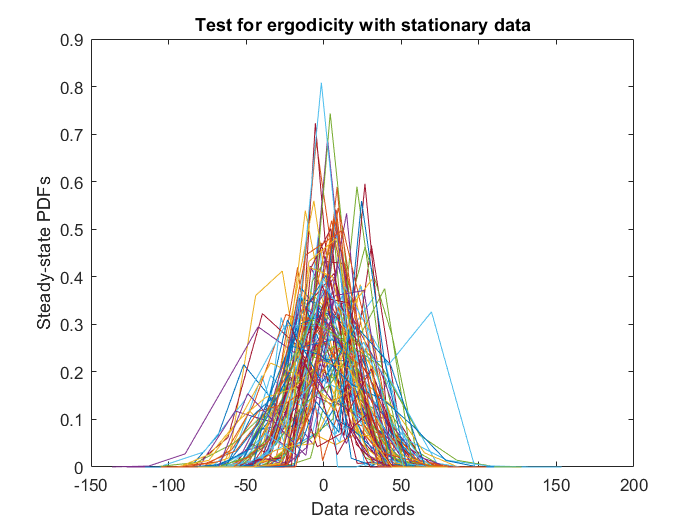



dataStationary = data(indexStationary);

figure();

for i = 1 : numberOfStationarySignals
    
    timeSeriesData = dataStationary(i).x;
    [p, x] = hist(timeSeriesData); 
    %Plot distribution
    plot(x, p/sum(p));
    hold on;
    
end

title('Test for ergodicity with stationary data');
xlabel('Data records');
ylabel('Steady-state PDFs');
hold off;

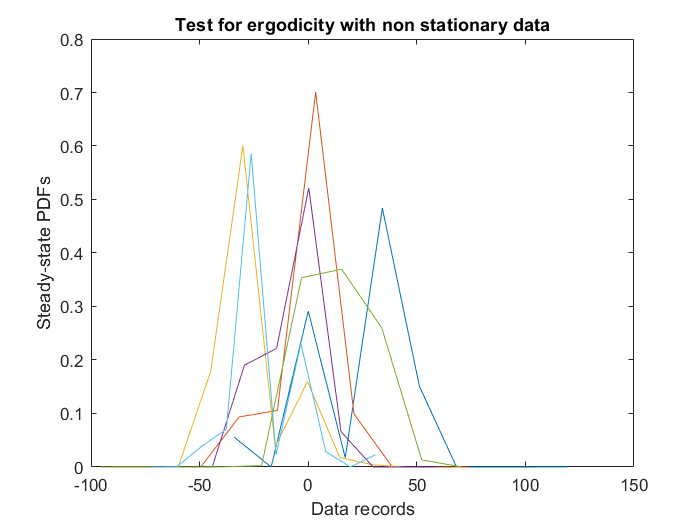


dataNonStationary = data(indexNonStationary);

figure();

for i = 1 : numberOfNonStationarySignals
    
    timeSeriesData = dataNonStationary(i).x;
    [p, x] = hist(timeSeriesData); 
    %Plot distribution
    plot(x, p/sum(p));
    hold on;
    
end

title('Test for ergodicity with non stationary data');
xlabel('Data records');
ylabel('Steady-state PDFs');
hold off;

Ans:

Stationarity refers to distribution of random variables. In a stationary process, all the random varaibles have similar distributions. Which indicates that they have nearly same statistical descriptions. A signal is said to be stationary, if it were to be shifted by some time instance , the statistical descriptions will remain the same. 

Here inorder to check the stationarity of the signals, we have selected a range of oints from the center of the data in hand. The range of data consists of  2000 points which would be 20% of the data.

We have used the Phillips-Perron test for one root to judge the stationarity of the data. This test assess the null hypothesis of one root in univariate time series. If the vector of boolean decision is 1, then we can say that the test has rejected the unit null hypothesis, which would indicate that the process is stationary and if the vector is 0, then the test has failed to reject the unit null hypothesis. Which is to say that there is not enough evidence to suggest that the process is stationary.

With the data that we have selected from the range of 2000 points, we can see that out of 100 data structs, 94 of them have the vector of boolean decision as 1 and 6 of them are 0. Which indicates that 94 of them are stationary and 6 of them are non stationary.

Inorder to further prove the stationarity of the data, we did a plot of the timesries data for both stationary and non stationary set and found that all the stationary data have a similar distribution which is not the case for non stationary data.

A signal is said to be ergodic if the values of time averages can be used as estimates of ensemble averages. From the plots we can see that, since the stationary data distributions are similar, we can say they converge on similar statistical descriptions and hence are ergodic. The non stationary data plot suggests the ensemble averages are all over the place and hence not ergodic.

The data here is non stationary as the means are changing over time even though for a specific window we can find stationary signals.